# Ejemplo para modelo de regresión con dataset patients

El proceso general debe contener los siguientes pasos:

En este livescript de ejemplo se realizará con un dataset que modificaremos para que tengamos la presencia de datos atípicos y faltantes, de esta forma realizaremos una exploración sencilla de datos, removeremos datos faltantes, estimaremos datos faltantes, crearemos características adicionales y finalmente entrenaremos un modelo de regresión lineal simple con sus medidas de calidad

El objetivo del modelo de regresión será que estime la presión sistólica y diastólica del paciente a partir de las otras variables

## Importación de datos

Cargaremos el dataset patients y se realizarán algunas modificaciones para agregar datos faltantes que de manera didáctica removeremos y estimaremos

Cada que se ejecuta la sección para la importación de datos, los datos atípicos y borrados cambiarán!

% leemos tabla de datos
load patients
data = table(LastName,Location,Age,Gender,Height,Weight,Smoker,SelfAssessedHealthStatus,Systolic,Diastolic);
clearvars -except data

% eliminamos 5 registros de manera aleatoria en la columna de edad y peso vamos a
% querer identificar estas filas y eliminarlas
valor_aleatorio = randi(100,[1,5]);
data.Age(valor_aleatorio)=nan;
data.Weight(valor_aleatorio)=nan;

% Ordenamos las filas de nuestra tabla por estatura de menor a mayor, y eliminaremos 5
% registros consecutivos de la variable estatura, el objetivo será estimar estos valores en lugar
% de borrar las filas afectadas
data = sortrows(data,'Height');
valor_aleatorio = randi(90);
data.Height(valor_aleatorio:valor_aleatorio+5) = nan;

% agregaremos unas filas que deben ser identificadas como datos atípicos
temp_data = data(data.Height == 72,:);
temp_data.Age = temp_data.Age+70;
data = [data;temp_data];
data = sortrows(data,'LastName');
head(data)

      LastName                 Location               Age      Gender      Height    Weight    Smoker    SelfAssessedHealthStatus    Systolic    Diastolic
    _____________    _____________________________    ___    __________    ______    ______    ______    ________________________    ________    _________

    {'Adams'    }    {'VA Hospital'              }    48     {'Female'}      66       137      false          {'Excellent'}            127          83    
    {'Alexander'}    {'County General Hospital'  }    25     {'Male'  }      69       171      true           {'Good'     }            128          99    
    {'Allen'    }    {'VA Hospital'    

## Visualizar datos

Añada las gráficas que considere necesarias para la exploración y determinar donde están los datos atípicos y los faltantes

Los datos faltantes en la columna de estatura son los que queremos reconstruir

Los datos faltantes en otras columnas, debemos eliminar la fila completa, en caso de que se traslapen, será mas importante borrar la fila de ese registro

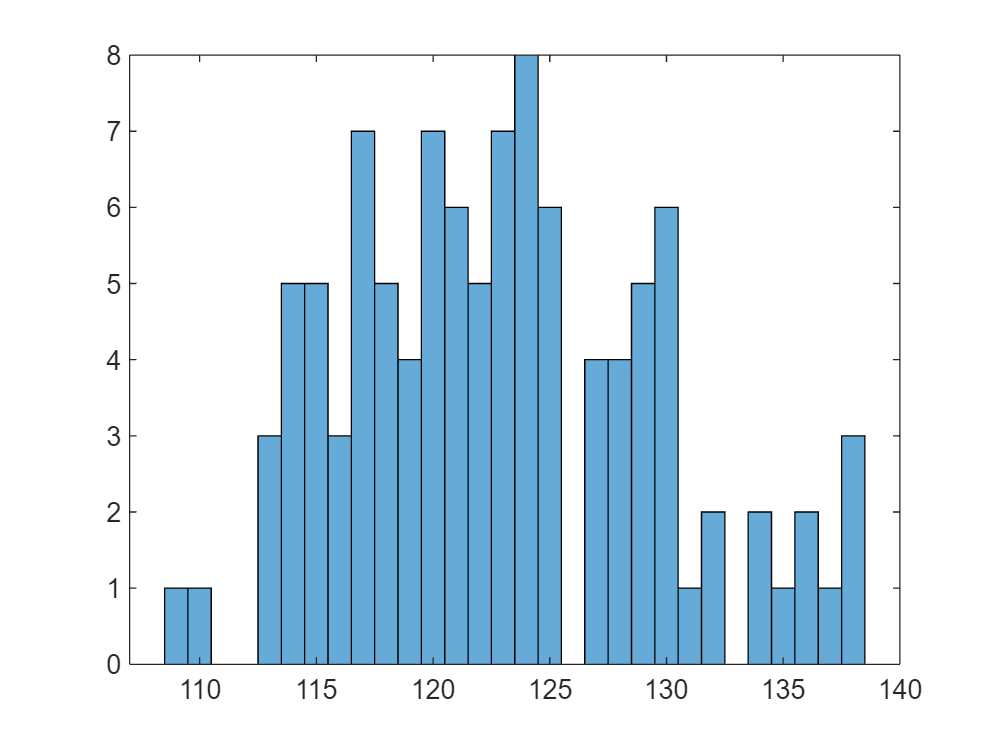

histogram(data.Systolic)

## Procesar datos faltantes

Se sugiere usar el task de clean missing data

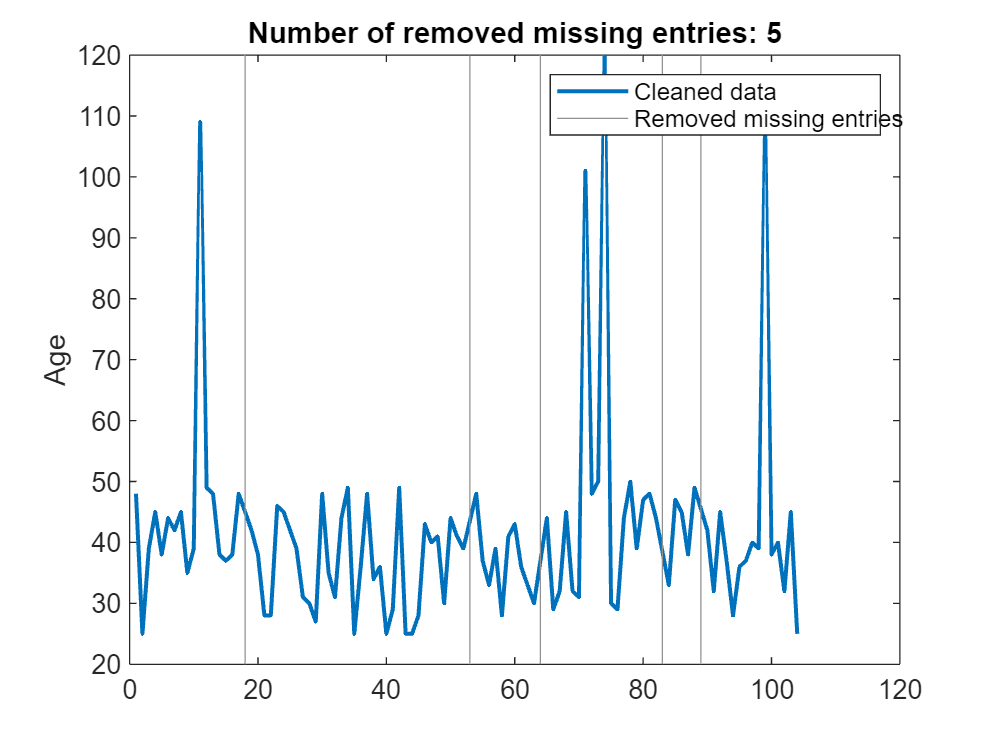

% Remove missing data
[data2,missingIndices] = rmmissing(data,"DataVariables","Age");

% Display results
clf
plot(find(~missingIndices),data2.Age,"Color",[0 114 189]/255,"LineWidth",1.5,...
    "DisplayName","Cleaned data")
hold on

% Plot removed missing entries
x = repelem(find(missingIndices),3);
y = repmat([ylim(gca) missing]',nnz(missingIndices),1);
plot(x,y,"Color",[145 145 145]/255,"DisplayName","Removed missing entries")
title("Number of removed missing entries: " + nnz(missingIndices))

hold off
legend
ylabel("Age")

clear x y


Ahora estimamos los datos faltantes

data2 = sortrows(data2,'Height');

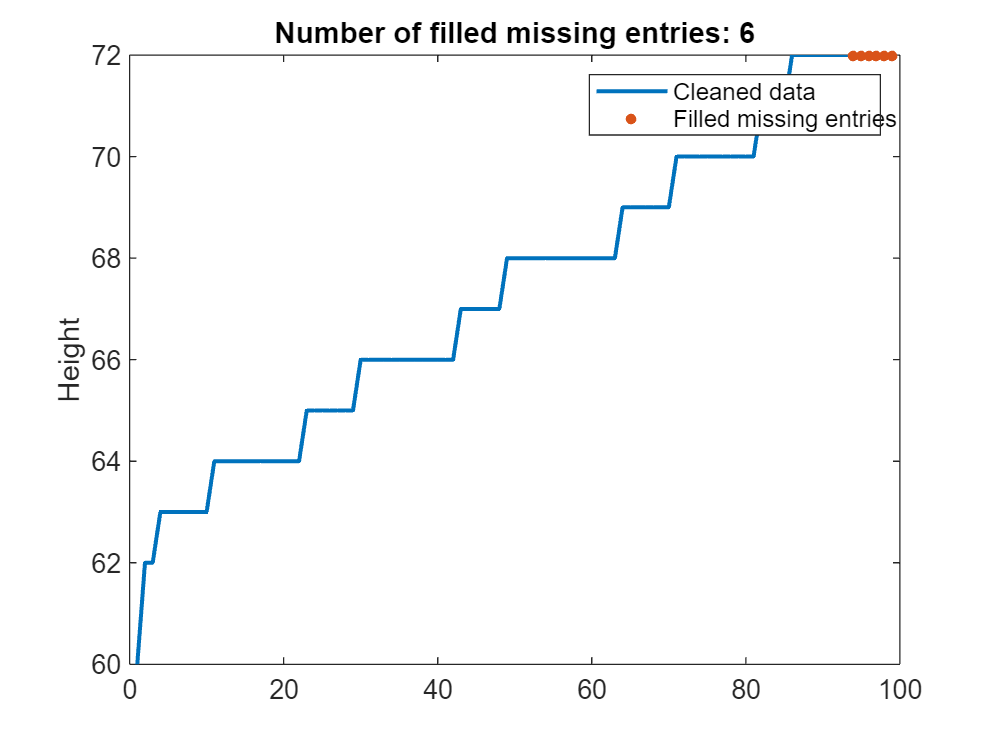

% Fill missing data
[data3,missingIndices2] = fillmissing(data2,"nearest",...
    "DataVariables","Height");

% Display results
clf
plot(data3.Height,"Color",[0 114 189]/255,"LineWidth",1.5,...
    "DisplayName","Cleaned data")
hold on

% Plot filled missing entries
plot(find(missingIndices2(:,5)),data3.Height(missingIndices2(:,5)),".",...
    "MarkerSize",12,"Color",[217 83 25]/255,...
    "DisplayName","Filled missing entries")
title("Number of filled missing entries: " + nnz(missingIndices2(:,5)))

hold off
legend
ylabel("Height")

clear missingIndices2

## Procesar datos atípicos

Se sugiere usar el task de clean outlier data

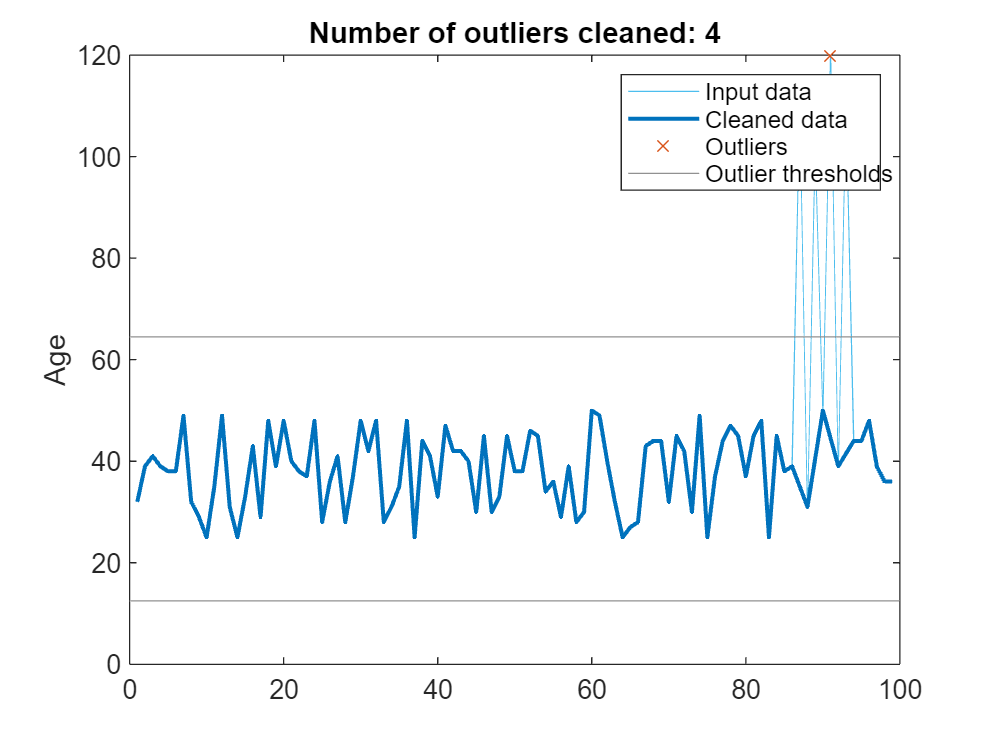

% Remove outliers
[data4,outlierIndices] = rmoutliers(data3,"quartiles","DataVariables","Age");

% Display results
clf
plot(data3.Age,"Color",[77 190 238]/255,"DisplayName","Input data")
hold on
plot(find(~outlierIndices),data4.Age,"Color",[0 114 189]/255,"LineWidth",1.5,...
    "DisplayName","Cleaned data")

% Plot outliers
plot(find(outlierIndices),data3.Age(outlierIndices),"x",...
    "Color",[217 83 25]/255,"DisplayName","Outliers")
title("Number of outliers cleaned: " + nnz(outlierIndices))

% Additional outlier computations for plot
[~,thresholdLow,thresholdHigh] = isoutlier(data3.Age,"quartiles");

% Plot outlier thresholds
plot([xlim missing xlim],[thresholdLow*[1 1] NaN thresholdHigh*[1 1]],...
    "Color",[145 145 145]/255,"DisplayName","Outlier thresholds")

hold off
legend
ylabel("Age")

clear thresholdLow thresholdHigh

## Crear variables adicionales

Podemos crear nuevas columnas para mejorar la lectura de la tabla, como peso y altura en kilogramos y centimetros respectivamente, además de incluir el indice de masa corporal

% Agregamos columna de altura y peso en cm y kg
data4.Altura_m = data4.Height /39.37;
data4.Peso_kg = data4.Weight / 2.205;

% Agregamos columna de BMI
data4.BMI = data4.Peso_kg ./ (data4.Altura_m .* data4.Altura_m);


## Normalizar datos

Se sugiere usar el task de Normalize Data

Una forma de asegurarnos que todas las variables para alimentar nuestro modelo de regresión lineal están listas, es con la gráfica boxplot, ahi podremos justificar que todas tienen una distribución similar sin datos atípicos considerables

No hay que normalizar las variables relacionadas a presión sanguinea ya que esas serán nuestras salidas del modelo

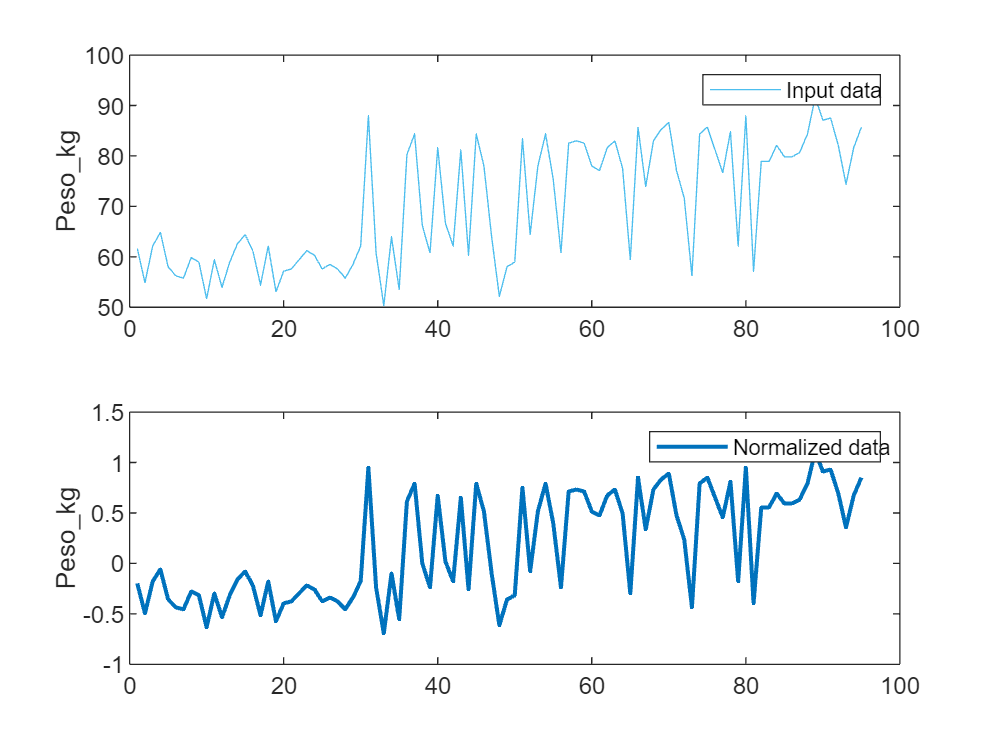

% Normalize Data
[data_normalizada, centering, scale] = normalize(data4,"center","median","scale","iqr",...
    "DataVariables",["Age","Altura_m","Peso_kg","BMI"]);

% Display results
clf
tiledlayout(2,1);
nexttile
plot(data4.Peso_kg,"Color",[77 190 238]/255,"DisplayName","Input data")
legend
ylabel("Peso_kg","Interpreter","none")

nexttile
plot(data_normalizada.Peso_kg,"Color",[0 114 189]/255,"LineWidth",1.5,...
    "DisplayName","Normalized data")
legend
ylabel("Peso_kg","Interpreter","none")

figure

## Salvemos nuestra tabla ya normalizada con la cual podemos entrenar modelos de regresión

save datos_entrenamiento.mat data_normalizada -mat

## Entrenar modelos de regresión lineal

Deben entrenarse dos modelos, las variables de presión sanguinea serán la salida (no pueden usarse para entrenamiento)

Crear nueva tabla con datos nuevos que nosotros podamos definir, supongamos que tenemos nuevas observaciones

Age = [38;60;80];
Altura_m = [1.60;1.60;1.50];
BMI = [20;25;22];
Peso_kg = [50;55;50];
nuevos_datos = table(Age,Altura_m,BMI,Peso_kg)

nuevos_datos = 3×4 table
    Age    Altura_m    BMI    Peso_kg
    ___    ________    ___    _______

    38       1.6       20       50   
    60       1.6       25       55   
    80       1.5       22       50   


## Evaluación del modelo

Agregue las medidas de calidad y explique los resultados, ¿es bueno el modelo? que limitantes podría tener? ¿está sobre entrenado?

## Probando el modelo

Intente con nuevos valores, su modelo de tal forma que pueda "crear" un nuevo registro y el modelo trate de predecir sus niveles de presión sanguínea

x = trainedModel.predictFcn(nuevos_datos)

Unable to resolve the name 'trainedModel.predictFcn'.

nuevos_datos_normalizados = normalize(nuevos_datos,"center",centering,"scale",scale,...
    "DataVariables",["Age","Altura_m","Peso_kg","BMI"]);
x1 = trainedModel.predictFcn(nuevos_datos_normalizados)


Ahora debemos hacer pasos similares con los datos del rio presidio